# Jared Ham

Mech 513 - Midterm Project

How Fast do Humans Walk on Mars?

### **1. Project Background**

    It is year 2040, and Mars is being researched for colonization. Locations for bases on Mars are being determined and one criteria that must be considered is disaster planning. As part of disaster planning, the scenario where a mars base has an emergency failure and all members of the base must evacuate to another base must be considered. In this scenario, the Mars astronauts must be able to to transit from one base to the other in less than a day of walking. It is also desireable to have the bases far apart to allow for data to be sampled from a wide varity of locations on Mars. 

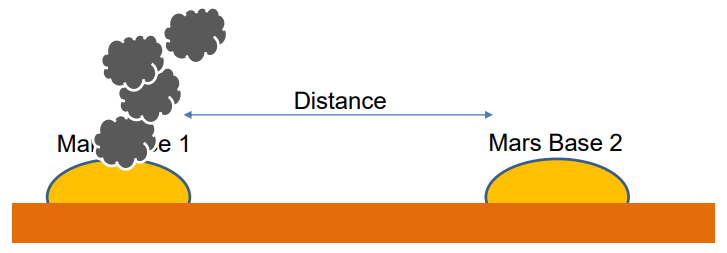

Figure 1: Disaster Scenario

    The acceleration due to gravity on Mars is 3.7 $\frac{m}{s^2 }$ which is about one third of that on earth.  How can we quantify the change in walking speed? Through the Froude Number, a dimensiolness quanity that is used to characterize gait transition and is caluclated using the equation below, v is velocity, g is acceleration due to gravity and L is the length from the ground to the hip joint. 


$$\mathrm{Fr}=\frac{v^2 }{g*L}$$


   Based on past research done with the Froude number, a person walks most efficiently at a Froude number of 0.25. And the transition between walking and running occurs at a Froude number of 0.5. In order to determine a confidence interval around the predicitons of walkning velocity on Mars using the Froude number, an experiment on earth will be run. In the experiment the participants will fast walk as fast as they can (this puts them on the edge of walking/running). This will then correspond to a Froude number of 0.5. This data will then be analyzed using Kline McClintock and monte carlo methods, and then extrapolated to a walking speed on Mars. 

### 2. Validation Procedures and Uncertaintity Quantificatio

distanceWalked = 10; %meters
g_earth = 9.81; %m/s^2
classData = [5.65 4.89 4.73 4.96 6.06 4.26 4.99 ; 38.25 37 38 36 32 35 42]'; % time in seconds, length in inches
classData = [classData(:, 1), classData(:,2) * .0254]; %convert leg length to meters
assumedFroudeNumber = 0.5;
froudeVelocity = sqrt(assumedFroudeNumber * g_earth * classData(:, 2) );
experimentVelocity = distanceWalked ./ classData(:,1);
